% Define the data for lower limit, upper limit, and frequency
lowerLimits = [0,1,2.5,3.5,4,5,7.5,9]; 
upperLimits = [1,2.5,3.5,4,5,7.5,9,10]; 
frequencies = [39,60,172,30,23,20,15,10];  

% Create a table in MATLAB
dataTable = table(lowerLimits', upperLimits', frequencies',...
    'VariableNames', {'LowerLimit', 'UpperLimit', 'Frequency'});

% Display the table
disp(dataTable);

    LowerLimit    UpperLimit    Frequency
    __________    __________    _________

         0             1            39   
         1           2.5            60   
       2.5           3.5           172   
       3.5             4            30   
         4             5            23   
         5           7.5            20   
       7.5             9            15   
         9            10            10   




% Calculate mean, median, mode, and standard deviation
data = [];
for i = 1:length(lowerLimits)
    data = [data, ones(1, frequencies(i)) * ((upperLimits(i) + lowerLimits(i)) / 2)];
end

meanValue = mean(data);
medianValue = median(data);
modeValue = mode(data);
stdDeviation = std(data);

% Calculate empirical_mode, mode_shift, and Karl
empirical_mode = 3 * medianValue - 2 * meanValue;
mode_shift = modeValue - empirical_mode;
Karl = (meanValue - modeValue) / stdDeviation;

% Display the calculated statistics
fprintf('Mean: %.2f\n', meanValue);

Mean: 3.25


fprintf('Median: %.2f\n', medianValue);

Median: 3.00


fprintf('Mode: %.2f\n', modeValue);

Mode: 3.00


fprintf('Standard Deviation: %.2f\n', stdDeviation);

Standard Deviation: 1.97


fprintf('Empirical Mode: %.2f\n', empirical_mode);

Empirical Mode: 2.49


fprintf('Mode Shift: %.2f\n', mode_shift);

Mode Shift: 0.51


fprintf('Karl: %.2f\n', Karl);

Karl: 0.13


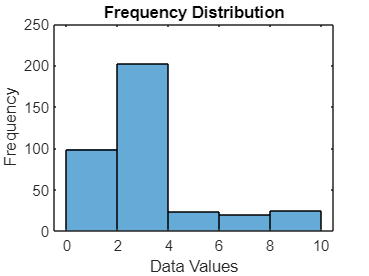


% Plotting the line graph
figure;
histogram(data, 'BinWidth', 2); % Change the 'BinWidth' according to your preference
title('Frequency Distribution');
xlabel('Data Values');
ylabel('Frequency');